# Calculating Correlations

Instructions are in the task pane to the left. Complete and submit each task one at a time.

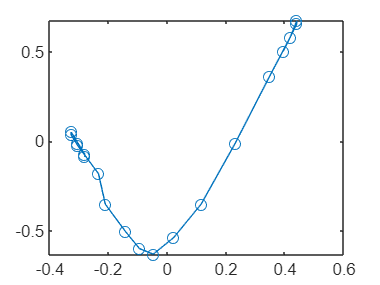

%Do not edit. This code loads and plots the data.
load sampleletters.mat
plot(v2.X,v2.Y,"o-")

## Task 1

For the first half of the letter V, the horizontal and vertical positions have a strong negative linear correlation: when the horizontal position increases, the vertical position decreases proportionally. Similarly, for the second half, the positions have a strong positive correlation: when the horizontal position increases, the vertical position also increases proportionally.

The `corr` function calculates the linear correlation between variables.

`C` `=` `corr``(``x``,``y``)``;`

**TASK**

Use the `corr` function to calculate the linear correlation between `v2.X` and `v2.Y`. Store the result in a variable called `C`.

**Hint**

Pass `v2.X` and `v2.Y` as inputs to the `corr` function.

C=corr(v2.X,v2.Y)

C = NaN

## Task 2

Because both variables contain missing data, `C` is `NaN`. You can use the `"Rows"` option to specify how to avoid missing values.

`C` `=` `corr``(``x``,``y``,``"Rows"``,``"complete"``)``;`

**TASK**

Recalculate the correlation between `v2.X` and `v2.Y`, this time with the `"Rows"` option set to `"complete"`. Store the result in `C`.

**Hint**

When calling the `corr` function, add the option `"Rows"` with the value `"complete"`.

C=corr(v2.X,v2.Y,"Rows","complete")

C = 0.6493

## Task 3

The correlation coefficient is always between -1 and +1.

- A coefficient of -1 indicates a perfect negative linear correlation

- A coefficient of +1 indicates a perfect positive linear correlation

- A coefficient of 0 indicates no linear correlation

In this case, there is only a moderate correlation because the calculation has been performed on the entire signal. It may be more informative to consider the two halves of the signal separately.

**TASK**

Use concatenation (`[` `]`) to make a matrix `M` with four columns: the first half (elements 1 to 11) of `v2.X`, the first half of `v2.Y`, the second half (elements 12 to 22) of `v2.X`, the second half of `v2.Y`.

**Hint**

Use square brackets to horizontally concatenate `v2.X``(``1``:``11``)`, `v2.Y``(``1``:``11``)`, `v2.X``(``12``:``22``)`, and `v2.Y``(``12``:``22``)`.

M = [v2.X(1:11) v2.Y(1:11) v2.X(12:22) v2.Y(12:22)]

M =    -0.2803   -0.0879   -0.0476   -0.6307
   -0.2803   -0.0724    0.0222   -0.5376
   -0.2803   -0.0724    0.1152   -0.3515
   -0.3035   -0.0103    0.2315   -0.0103
   -0.3268    0.0517    0.3478    0.3619
   -0.3268    0.0362    0.4176    0.5790
   -0.3035   -0.0258    0.4409    0.6720
   -0.2337   -0.1809    0.4409    0.6565
   -0.2105   -0.3515    0.4176    0.5790
   -0.1407   -0.5066    0.3943    0.5014


## Task 4

To calculate the correlation between each pair of several variables, you can pass a matrix to the `corr` function, where each variable is a column of the matrix.

`M` `=` `[``x` `y` `z``]``;`

`C` `=` `corr``(``M``)``;`

**TASK**

Use the `corr` function to calculate the correlations between the columns of `M`. Store the result in a variable called `Cmat`. Don't forget to ignore missing values.

**Hint**

Pass the matrix `M` to the `corr` function. Also include the `"Rows"` option set to `"complete"`.

Cmat=corr(M,"Rows","complete")

Cmat =     1.0000   -0.9896    0.2166    0.2231
   -0.9896    1.0000   -0.2465   -0.2548
    0.2166   -0.2465    1.0000    0.9956
    0.2231   -0.2548    0.9956    1.0000


## Further Practice

The output `Cmat` is a 4-by-4 matrix of the coefficients of correlation between each pairwise combination of the columns of `M`. That is, `Cmat``(``j``,``k``)` is the correlation of `M``(``:,``j``)` and `M``(``:,``k``)`. The matrix is symmetric because the correlation between `x` and `y` is the same as the correlation between `y` and `x`. The diagonal elements are always equal to 1, because a variable is always perfectly correlated with itself.

Which variables are highly correlated? Remember that the first two columns of `M` are the horizontal and vertical positions of the first half of the signal; the last two columns are the second half of the signal. Are the correlation coefficients what you expect? Try calculating the same correlations for `v2` and for some other sample letters. Could the correlation coefficients be useful features to distinguish between letters?